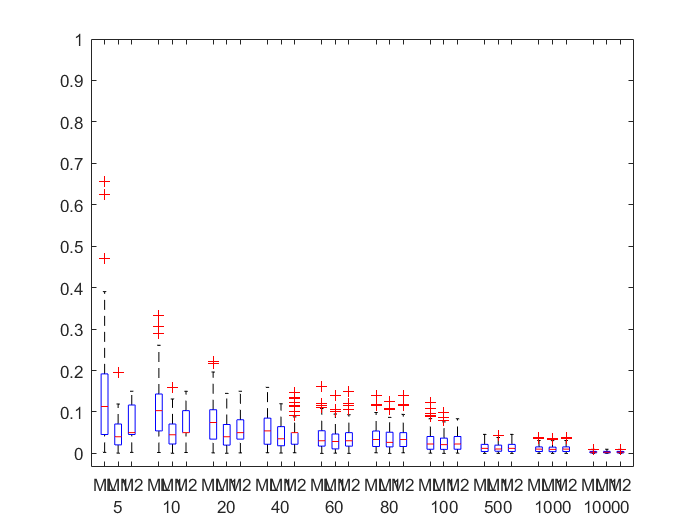

N_arr=[5, 10, 20, 40, 60, 80, 100, 500, 1000, 10000];
MLE=zeros(100, 10);
MAP1=zeros(100, 10);
MAP2=zeros(100, 10);
rng(1);
for i = 1:10
    N=N_arr(i);
    for n=1:100
        a=zeros(N, 1);
        for j=1:N
            a(j)=randn()*4+10;
        end
        MLE(n,i)=abs(sum(a)/N-10)/10;
        MAP1(n,i)=abs(((sum(a)/N)+(16*10.5/N))/((1)+(16)/N)-10)/10;
        if sum(a)/N<9.5
            MAP2(n,i)=abs(9.5-10)/10;
        elseif sum(a)/N>11.5
            MAP2(n,i)=abs(11.5-10)/10;
        else
            MAP2(n,i)=MLE(n,i);
        end
            
    end
end
data={MLE, MAP1, MAP2};
boxplotGroup(data, 'PrimaryLabels', {'ML', 'M1', 'M2'}, 'SecondaryLabels', {'5', '10', '20', '40', '60', '80', '100', '500', '1000', '10000'});